% 加载测试数据和标签
gTruthFile = '/home/lzh/hair/seg_test/gTruth_250test_20241208.mat'; 
load(gTruthFile); % 加载 groundTruth 数据
% 测试图像
% 从 gTruth 提取测试图像路径
imageFilePaths = gTruth.DataSource.Source; % 获取测试图像文件路径

% 创建一个 ImageDatastore 对象
imdsTest = imageDatastore(imageFilePaths);

% 从 gTruth 提取标签路径、类别和像素标签 ID
labelPaths = gTruth.LabelData.PixelLabelData; % 标签路径
classNames = gTruth.LabelDefinitions.Name; % 类别名称
labelIDs = gTruth.LabelDefinitions.PixelLabelID; % 像素标签 ID

% 创建 pixelLabelDatastore
pxdsTest = pixelLabelDatastore(labelPaths, classNames, labelIDs);

% 加载五个已训练的网络
networkFolder = '/home/lzh/hair/trainedModel_unet_segnet_deeplab';
networkFiles = {'trainedUNet.mat', 'trainedSegnet_1112.mat', 'trainedSegnet_0005.mat', 'trainedDeeplabv3plus_20241117.mat', 'trainedDeeplabv3plus_0005.mat'}; 
inputSizes = {[1024 1280 1], [512 640 3], [512 640 3], [512 640 3], [512 640 3]}; 
numNetworks = numel(networkFiles);
networks = cell(1, numNetworks);

% 初始化存储评估指标的表
metricsTable = table('Size', [numNetworks, 3], ...
                     'VariableTypes', {'double', 'double', 'double'}, ...
                     'VariableNames', {'GlobalAccuracy', 'MeanIoU', 'MeanAccuracy'});

for i = 1:numNetworks
    networkPath = fullfile(networkFolder, networkFiles{i}); 
    loadedData = load(networkPath);
     % 动态检查网络变量名称并提取
    if isfield(loadedData, 'net') % 检查是否存在变量 net
        networks{i} = loadedData.net;
    elseif isfield(loadedData, 'lgraph') % 检查是否存在变量 lgraph
        networks{i} = loadedData.lgraph;
    else
        error('File %s does not contain a valid network variable (net or lgraph).', networkFiles{i});
    end
    % 提取对应的输入大小
    inputSize = inputSizes{i};
    % 调整 pxdsTest 的大小
    resizedPxdsTest = pixelLabelDatastore(pxdsTest.Files, pxdsTest.ClassNames, gTruth.LabelDefinitions.PixelLabelID);

    
    % 动态调整标签图像大小
    resizedPxdsTest.ReadFcn = @(filename) imresize(imread(filename), inputSize(1:2), 'nearest');


    % 判断是否需要三通道
    isThreeChannel = inputSize(3) == 3;

    % 动态调整 ReadFcn
    if isThreeChannel
        % 灰度图像转换为三通道并调整大小
        imdsTest.ReadFcn = @(filename) imresize(repmat(imread(filename), 1, 1, 3), inputSize(1:2));
    else
        % 单通道网络直接调整大小
        imdsTest.ReadFcn = @(filename) imresize(imread(filename), inputSize(1:2));
    end
    
    % 预测并计算评估指标
    pxdsPred = semanticseg(imdsTest, networks{i}, 'MiniBatchSize', 4, 'Verbose', false);
        
    % 计算评估指标
    metrics = evaluateSemanticSegmentation(pxdsPred, resizedPxdsTest);
    
    % 保存指标
    metricsTable.GlobalAccuracy(i) = metrics.DataSetMetrics.GlobalAccuracy;
    metricsTable.MeanIoU(i) = metrics.DataSetMetrics.MeanIoU;
    metricsTable.MeanAccuracy(i) = metrics.DataSetMetrics.MeanAccuracy;
end

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 250 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

        0.9472          0.94877       0.89454      0.90511        0.77788  

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 250 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.91521          0.92348       0.77379      0.85678        0.69987  

Evaluating semantic segmentation results
-------------------------------------


% 显示结果
disp(metricsTable);

    GlobalAccuracy    MeanIoU    MeanAccuracy
    ______________    _______    ____________

        0.9472        0.89454      0.94877   
       0.91521        0.77379      0.92348   
        0.9194          0.777       0.9289   
       0.92589        0.78488       0.8959   
         0.896        0.73961      0.90938   



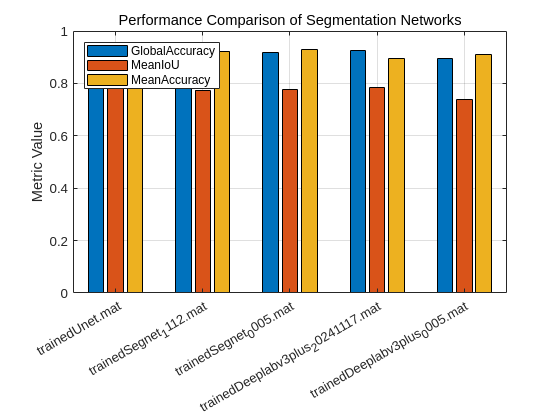


% 绘制柱状图比较各网络性能
figure;
bar(metricsTable.Variables);
set(gca, 'XTickLabel', {'trainedUnet.mat', 'trainedSegnet_1112.mat', 'trainedSegnet_0005.mat', 'trainedDeeplabv3plus_20241117.mat', 'trainedDeeplabv3plus_0005.mat'});
legend(metricsTable.Properties.VariableNames, 'Location', 'northwest');
ylabel('Metric Value');
title('Performance Comparison of Segmentation Networks');
grid on;